**The Tabular value-fucntion methods on the cart and pole system**

Consider the cart-and-pole system here depicted:

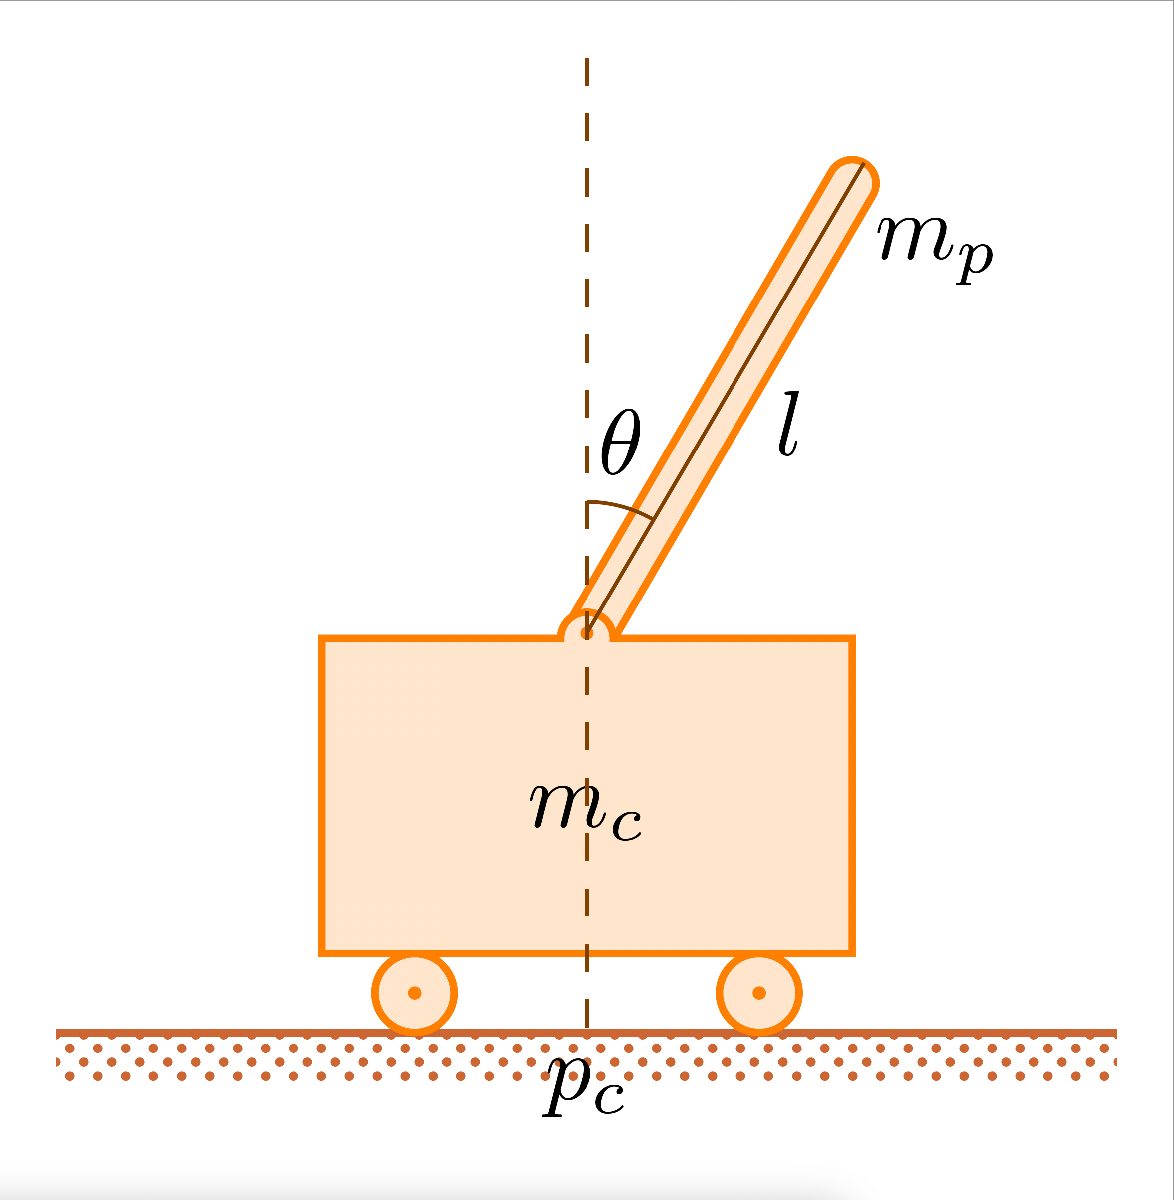

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient.

1.Given the $$\mathcal{X}$$, $$\mathcal{U}$$ of the first hands-on define: the set of possible initial conditions of an episode; the terminal conditions of the episode

The set of possible initial conditions is defined as

                             
$$x(0) = \left( \begin{array}{ccc}
                cp \\
                \dot cp \\
                \theta \\
                \dot \theta
\end{array} \right)
=
 \left( \begin{array}{ccc}
                \{0\} \ m \\
                 \{-1, +1\} \ m/sec\\
                \{- 10, + 10 \}\ deg \\
                \{-0.1, +0.1\} \ rad/sec
\end{array} \right);$$


                             
$$u(0) = 0 \ N;
$$


and the terminal episodes are:

- if the pole is going to fall, $\theta > \{-15,\ +15 \} \ deg
$ or the cart position is going out of the constraints $cp = \{ -5, +5\}\ m;$

- if the control input overcome the limit force $u = \{-10, +10\} \ N$

- if the episode (250 steps when the system will be discretized) overcome the limit of $5 \sec$.

close all
clear
clc

uplim = [ 5;
          3
          deg2rad(15);
          3];

lowlim = -1 * uplim;
max_steps = 250;

2. Provide a proper discretization of the state space $$\mathcal{X}$$, and define the size of the action-value function $Q$

In the process of system discretization, both the cart’s position and speed will be segmented into 10 parts each.

Similarly, the angular speed will be broken down into 10 steps. However, the angular position will be divided into a larger number of steps, specifically 20.

The size of the cation-value function $Q
$ wil be $|pc| \cdot |\dot pc| \cdot |\theta| \cdot |\dot \theta|$

vectDiscr = [10; 10; 20; 10];

3. Create a code able to select the discretized version of a measured state $x$

4. Given the terminal conditions of the episode (selected in 1.) create a code able to perform a fixed number of episodes of a fixed number of steps, starting from random initial conditions and applying random inputs.

5. Create a function able to perform $$\epsilon$$-greedy policy for a chosen $$\epsilon$$.

6. Create a code that applies Tabular Q-Learning algorithm.

g = 9.8;
mc = 1;
mp = 0.1;
l = 0.5;
mu_p = 2e-6;

Ts = 0.02;
t_zero = 0;

total_episodes = 1000;
learning_rate = 0.1;           % Alpha
gamma = 0.95;     

epsilon = 1.0;          % This choice ensure high exploration in the first episodes
max_epsilon = 1.0;     
min_epsilon = 0.01;     % This guarantees that also in the last episodes there is some
                        % exploration, not only exploitation
decay_rate = 0.0001;    % I want to ensure high exploration during the first episodes

num_action = 2; % +10 or -10 N

%qtable = zeros([vectDiscr(1), vectDiscr(2), vectDiscr(3), vectDiscr(4), num_action]);

**IMPORTANT : **The code in the above line is used only if it's the first run or if the file "qtable.mat" does not exist

load qtable.mat;  % The code in the above line is used only if it's the first run

rewards = zeros(1, total_episodes);

% Loop over each episode
for episode = 1:total_episodes

    x0_rand = get_initState();
    
    [x_cp, x_cpd, x_th, x_thd] = discretize_state(x0_rand, lowlim, uplim, vectDiscr);
    x0_discr = [x_cp, x_cpd, x_th, x_thd];
    total_rewards = 0;
    
    % Loop over each step in one episode
    for step = 1:max_steps

        exp_exp_tradeoff = rand();

        % If this number is greater than epsilon we will do exploitation 
        if exp_exp_tradeoff > epsilon
            [~, bool_F] = max(qtable(x0_discr(1), x0_discr(2), x0_discr(3), x0_discr(4), :));
        % Else doing we do a random choice,resulting in more exploration
        else
            bool_F = randi([1,2]);
        end
        
        % Convert action into force
        if bool_F == 2
            F = 10;
        else
            F = -10;
        end

        % Simulation
        t1 = t_zero + Ts;
        t_sim = [t_zero, t1];
        [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, F), t_sim, x0_rand);
        new_x0_rand = x(end, :);
        [nx_cp, nx_cpd, nx_th, nx_thd] = discretize_state(new_x0_rand, lowlim, uplim, vectDiscr);
        new_x0 = [nx_cp, nx_cpd, nx_th, nx_thd];
        t_zero = t1;
        
        % Check if the new state is terminal
        stop = should_stop(new_x0, vectDiscr);
        if (stop == 1)
            reward = -100;  % assign penaly
        else
            reward = 1;     % assign reward
        end

        % Update Q(s,a)
        qtable(x0_discr(1), x0_discr(2), x0_discr(3), x0_discr(4), bool_F) =...
              qtable(x0_discr(1), x0_discr(2), x0_discr(3), x0_discr(4), bool_F) + learning_rate * (reward + gamma * max(qtable(new_x0(1), new_x0(2), new_x0(3), new_x0(4), :))...
              - qtable(x0_discr(1), x0_discr(2), x0_discr(3), x0_discr(4), bool_F)); %#ok<*SAGROW>
        
        % Update the total rewards
        total_rewards = total_rewards + reward;
        
        % Update the state for iteration
        x0_discr = new_x0;
        x0_rand = new_x0_rand;

        % If the system goes out of its boundaries the STOP
        stop = should_stop(new_x0, vectDiscr);
        if (stop == 1)
            break;
        end
    end
    
    % Reduce epsilon (more exploitation, less exploration)
    epsilon = min_epsilon + (max_epsilon - min_epsilon)*exp(-decay_rate*episode); 
    rewards(episode) = total_rewards;
end

sum(rewards)/total_episodes

ans = -79.3030

epsilon

epsilon = 0.9058

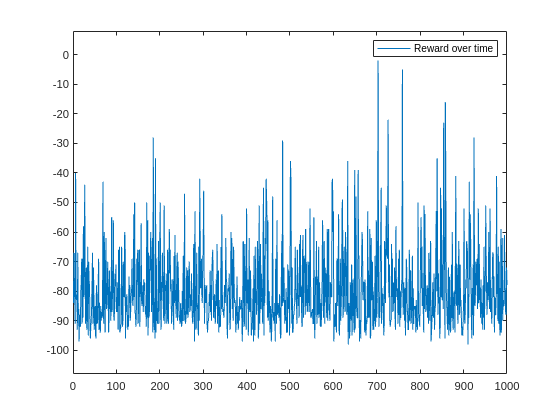

plot(rewards); 
legend('Reward over time');
ylim([min(rewards)-10, max(rewards)+10]);

**Simulation of the system (Q-Learning)**

x0_rand = get_initState();

U = [];
x_out = [];
t_out = [];
t_zero = 0;

[x_cp, x_cpd, x_th, x_thd] = discretize_state(x0_rand, lowlim, uplim, vectDiscr);
x0_discr = [x_cp, x_cpd, x_th, x_thd];

for step = 1:max_steps
    [~, bool_F] = max(qtable(x0_discr(1), x0_discr(2), x0_discr(3), x0_discr(4), :));

    if bool_F == 2
        F = 10;
    else
        F = -10;
    end
    
    U = [U, F]; %#ok<*AGROW>

    t1 = t_zero + Ts;
    t_sim = [t_zero, t1];
    [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, F), t_sim, x0_rand);

    x_out = [x_out; x(end, :)];
    t_out = [t_out, t(end)];

    new_x0_rand = x(end, :);
    [nx_cp, nx_cpd, nx_th, nx_thd] = discretize_state(new_x0_rand, lowlim, uplim, vectDiscr);
    new_x0 = [nx_cp, nx_cpd, nx_th, nx_thd];
    t_zero = t1;

    x0_discr = new_x0;
    x0_rand = new_x0_rand;

    stop = should_stop(new_x0, vectDiscr);
    if (stop == 1)
        break;
    end
end

save ('qtable.mat', 'qtable');

Plot of the simulation

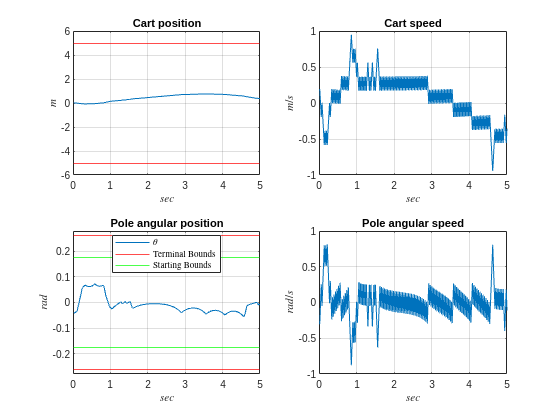

close all
subplot(2,2,1);
plot(t_out, x_out(:,1));
hold on
yline(5, 'r');
yline(-5, 'r');
hold off
xlim([0, 5]);
ylim([-6, 6]);
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
title("Cart position");

subplot(2,2,2);
plot(t_out, x_out(:,2));
grid on
xlim([0, 5]);
xlabel("$sec$", Interpreter="latex");
ylabel("$m/s$", Rotation=90, Interpreter="latex");
title("Cart speed");

subplot(2,2,3);
plot(t_out, x_out(:,3));
hold on;
yline(deg2rad(15), 'r');
yline(deg2rad(-15), 'r');
yline(deg2rad(10), 'g');
yline(deg2rad(-10), 'g');
hold off;
grid on;
xlim([0, 5]);
ylim([deg2rad(-16), deg2rad(16)]);
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
legend("$\theta$", "Terminal Bounds","", "Starting Bounds", Interpreter="latex", location='best');
title("Pole angular position");

subplot(2,2,4);
plot(t_out, x_out(:,4));
grid on
xlim([0, 5]);
xlabel("$sec$", Interpreter="latex");
ylabel("$rad/s$", Rotation=90, Interpreter="latex");
title("Pole angular speed");

Animation of the system

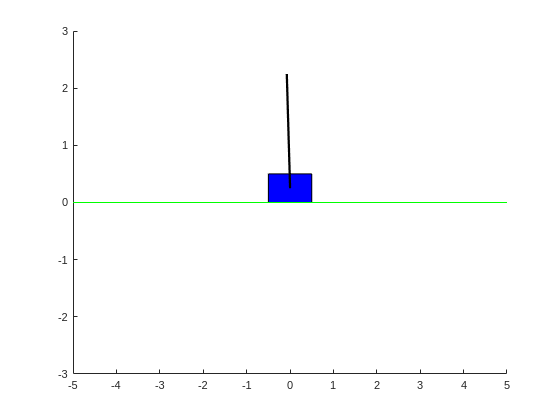

close all
animate_cartpole(t_out, x_out);

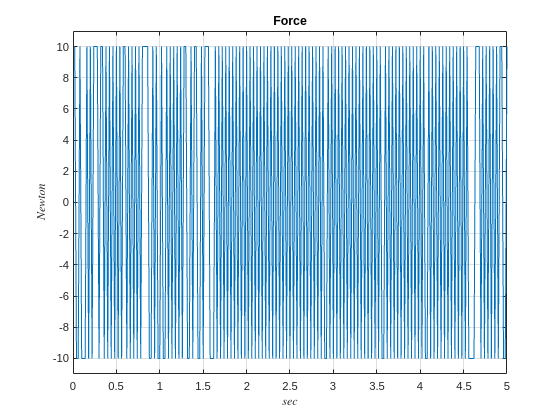

close all
plot(t_out, U);
grid on;
ylim([-11, 11]);
xlabel("$sec$", Interpreter="latex");
ylabel("$Newton$", Rotation=90, Interpreter="latex");
title("Force");

7. Copy and paste your Q-learning algorithm and apply the changes needed to convert it into a SARSA algorithm

close all

total_episodes = 1000;
learning_rate = 0.1;           % Alpha
gamma = 0.95;

epsilon = 1.0;  
max_epsilon = 1.0;  
min_epsilon = 0.01; 
decay_rate = 0.0001; 

%qtable_sarsa = zeros([vectDiscr(1), vectDiscr(2), vectDiscr(3), vectDiscr(4), num_action]);

**IMPORTANT : **The code in the above line is used only if it's the first run or if the file "qtable_sarsa.mat" does not exist

load qtable_sarsa.mat;  % The code in the above line is used only if it's the first run

rewards = zeros(1, total_episodes);

% Loop over each episode
for episode = 1:total_episodes

    x0_rand = get_initState();
    
    [x_cp, x_cpd, x_th, x_thd] = discretize_state(x0_rand, lowlim, uplim, vectDiscr);
    x0_discr = [x_cp, x_cpd, x_th, x_thd];
    total_rewards = 0;

    exp_exp_tradeoff = rand();

    % If this number is greater than epsilon we will do exploitation 
    if exp_exp_tradeoff > epsilon
        [~, bool_F] = max(qtable_sarsa(x0_discr(1), x0_discr(2), x0_discr(3), x0_discr(4), :));
    % Else doing we do a random choice,resulting in more exploration
    else
        bool_F = randi([1,2]);
    end
    
    % Loop over each step in one episode
    for step = 1:max_steps

        % Convert action into force
        if bool_F == 2
            F = 10;
        else
            F = -10;
        end

        % Simulation
        t1 = t_zero + Ts;
        t_sim = [t_zero, t1];
        [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, F), t_sim, x0_rand);
        new_x0_rand = x(end, :);
        [nx_cp, nx_cpd, nx_th, nx_thd] = discretize_state(new_x0_rand, lowlim, uplim, vectDiscr);
        new_x0 = [nx_cp, nx_cpd, nx_th, nx_thd];
        t_zero = t1;
        
        % Check if the new state is terminal
        stop = should_stop(new_x0, vectDiscr);
        if (stop == 1)
            reward = -100;  % assign penaly
        else
            reward = 1;     % assign reward
        end

        % If this number is greater than epsilon we will do exploitation 
        if exp_exp_tradeoff > epsilon
            [~, new_bool_F] = max(qtable_sarsa(x0_discr(1), x0_discr(2), x0_discr(3), x0_discr(4), :));
        % Else doing we do a random choice,resulting in more exploration
        else
            new_bool_F = randi([1,2]);
        end

        % Update Q(s,a)
        qtable_sarsa(x0_discr(1), x0_discr(2), x0_discr(3), x0_discr(4), bool_F) =...
              qtable_sarsa(x0_discr(1), x0_discr(2), x0_discr(3), x0_discr(4), bool_F) + learning_rate * (reward + gamma * (qtable_sarsa(new_x0(1), new_x0(2), new_x0(3), new_x0(4), new_bool_F))...
            - qtable_sarsa(x0_discr(1), x0_discr(2), x0_discr(3), x0_discr(4), bool_F)); %#ok<*SAGROW>
        
        % Update the total rewards
        total_rewards = total_rewards + reward;
        
        % Update the state for iteration
        x0_discr = new_x0;
        x0_rand = new_x0_rand;
        bool_F = new_bool_F;

        % If the system goes out of its boundaries the STOP
        stop = should_stop(new_x0, vectDiscr);
        if (stop == 1)
            break;
        end
    end
    
    % Reduce epsilon (more exploitation, less exploration)
    epsilon = min_epsilon + (max_epsilon - min_epsilon)*exp(-decay_rate*episode); 
    rewards(episode) = total_rewards;
end

sum(rewards)/total_episodes

ans = -68.5550

epsilon

epsilon = 0.9058

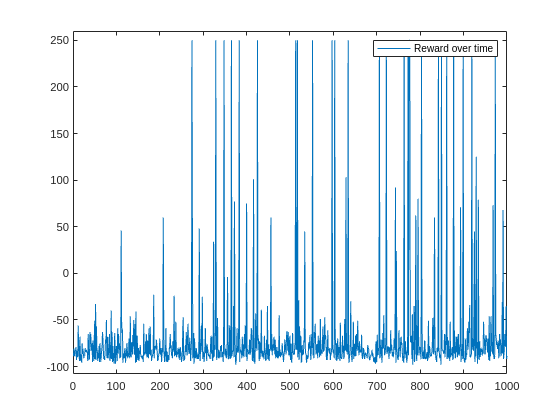

plot(rewards); 
legend('Reward over time');
ylim([min(rewards)-10, max(rewards)+10]);

**Simulation of the system (SARSA)**

x0_rand = get_initState();

U = [];
x_out = [];
t_out = [];
t_zero = 0;

[x_cp, x_cpd, x_th, x_thd] = discretize_state(x0_rand, lowlim, uplim, vectDiscr);
x0_discr = [x_cp, x_cpd, x_th, x_thd];

for step = 1:max_steps
    [~, bool_F] = max(qtable_sarsa(x0_discr(1), x0_discr(2), x0_discr(3), x0_discr(4), :));

    if bool_F == 2
        F = 10;
    else
        F = -10;
    end
    
    U = [U, F]; %#ok<*AGROW>

    t1 = t_zero + Ts;
    t_sim = [t_zero, t1];
    [t, x] = ode45(@(t,x)cart_pend_for(t, x, g, mp, mc, l, mu_p, F), t_sim, x0_rand);

    x_out = [x_out; x(end, :)];
    t_out = [t_out, t(end)];

    new_x0_rand = x(end, :);
    [nx_cp, nx_cpd, nx_th, nx_thd] = discretize_state(new_x0_rand, lowlim, uplim, vectDiscr);
    new_x0 = [nx_cp, nx_cpd, nx_th, nx_thd];
    t_zero = t1;

    x0_discr = new_x0;
    x0_rand = new_x0_rand;

    stop = should_stop(new_x0, vectDiscr);
    if (stop == 1)
        break;
    end
end

save ('qtable_sarsa.mat', 'qtable_sarsa');

Plot of the simulation

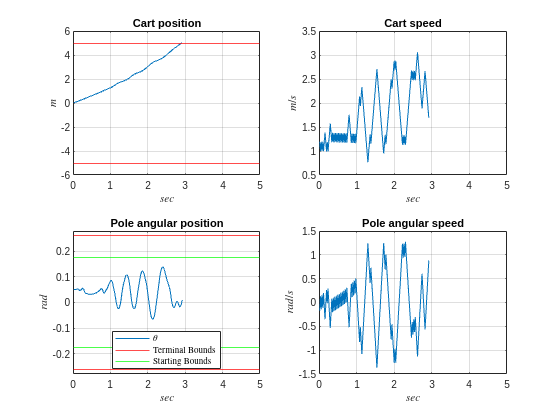

close all
subplot(2,2,1);
plot(t_out, x_out(:,1));
hold on
yline(5, 'r');
yline(-5, 'r');
hold off
xlim([0, 5]);
ylim([-6, 6]);
xlabel("$sec$", Interpreter="latex");
ylabel("$m$", Rotation=90, Interpreter="latex");
grid on
title("Cart position");

subplot(2,2,2);
plot(t_out, x_out(:,2));
grid on
xlim([0, 5]);
xlabel("$sec$", Interpreter="latex");
ylabel("$m/s$", Rotation=90, Interpreter="latex");
title("Cart speed");

subplot(2,2,3);
plot(t_out, x_out(:,3));
hold on;
yline(deg2rad(15), 'r');
yline(deg2rad(-15), 'r');
yline(deg2rad(10), 'g');
yline(deg2rad(-10), 'g');
hold off;
grid on;
xlim([0, 5]);
ylim([deg2rad(-16), deg2rad(16)]);
xlabel("$sec$", Interpreter="latex");
ylabel("$rad$", Rotation=90, Interpreter="latex");
legend("$\theta$", "Terminal Bounds","", "Starting Bounds", Interpreter="latex", location='best');
title("Pole angular position");

subplot(2,2,4);
plot(t_out, x_out(:,4));
grid on
xlim([0, 5]);
xlabel("$sec$", Interpreter="latex");
ylabel("$rad/s$", Rotation=90, Interpreter="latex");
title("Pole angular speed");

Animation of the system

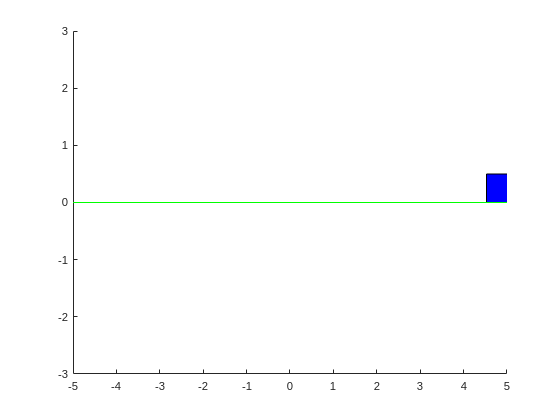

close all
animate_cartpole(t_out, x_out);

#### Conclusions

After conducting numerous trials, it has been noted that the SARSA algorithm converges more rapidly than Tabular Q-Learning. Moreover, the SARSA algorithm not only secures higher rewards than Q-Learning, but it also achieves them more quickly. Despite these differences, both methods have effectively converged to an optimal solution. In fact, in both scenarios, the pole remains near the equilibrium point for the entire duration of the simulation. It’s important to note that the simulation time was set to 5 seconds due to its significant impact on the efficiency of the algorithm. However, the system is capable of maintaining the pole in equilibrium for any desired length of time.

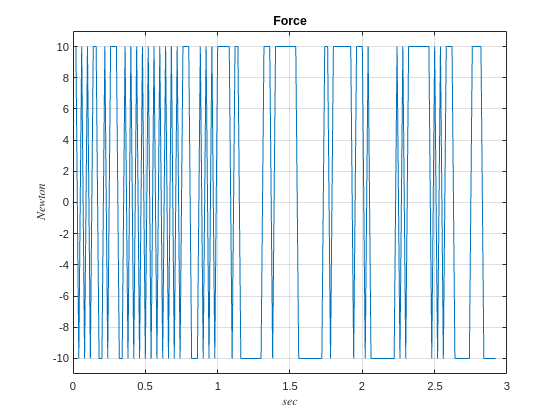

close all
plot(t_out, U);
grid on;
ylim([-11, 11]);
xlabel("$sec$", Interpreter="latex");
ylabel("$Newton$", Rotation=90, Interpreter="latex");
title("Force");

function dxdt = cart_pend_for(t, x, g, mp, mc, l, mu_p, U) %#ok<*INUSD>

  dxdt = zeros(4,1);

  dxdt(1) = x(2);
  dxdt(2) = (U+mp*l*((x(4)^2)*sin(x(3))-((g*sin(x(3))+ cos(x(3))*((-U-mp*l*(x(4)^2)*sin(x(3)))/(mc+mp))-((mu_p*x(4))/(mp*l)))/(l*((4/3)-((mp*cos(x(3))^2)/(mc+mp)))))*cos(x(3))))/(mc+mp);
  dxdt(3) = x(4);
  dxdt(4) = (g*sin(x(3))+ cos(x(3))*((-U-mp*l*(x(4)^2)*sin(x(3)))/(mc+mp))-((mu_p*x(4))/(mp*l)))/(l*((4/3)-((mp*cos(x(3))^2)/(mc+mp))));

end

function [iCartPos, iCartSpeed, iPolePos, iPoleSpeed ] = discretize_state(state, lowBound, upBound, numBin)
    
    cp = state(1);
    cp_dot = state(2);
    theta = state(3);
    theta_dot= state(4);
    
    cp_discr        = linspace(lowBound(1), upBound(1), numBin(1)+1);
    cp_dot_discr    = linspace(lowBound(2), upBound(2), numBin(4)+1);
    theta_discr     = linspace(lowBound(3), upBound(3), numBin(3)+1);
    theta_dot_discr = linspace(lowBound(4), upBound(4), numBin(4)+1);
    
    [~, ~, iCartPos] = histcounts(cp, cp_discr);
    [~, ~, iCartSpeed] = histcounts(cp_dot, cp_dot_discr);
    [~, ~, iPolePos] = histcounts(theta, theta_discr);
    [~, ~, iPoleSpeed] = histcounts(theta_dot, theta_dot_discr);

    iCartPos = max(iCartPos - 1, 1);
    iCartSpeed = max(iCartSpeed - 1, 1);
    iPolePos = max(iPolePos - 1, 1);
    iPoleSpeed = max(iPoleSpeed - 1, 1);
    
end

function stop = should_stop(dstate, numBins)
    if (dstate(1) <= 1 || dstate(1) >= numBins(1)) || (dstate(3) <= 1 || dstate(3) >= numBins(3))
    %if (dstate(3) == 1 || dstate(3) == (numBins(3)))
        stop = 1;
    else
        stop = 0;
    end
end

function initState = get_initState()
    %initState = [0, 0, deg2rad(randi([-10, 10])), 0];
    initState = [0, randi([-1, +1]), deg2rad(randi([-10, 10])), randi([-1, +1])/10];
end

function animate_cartpole(t, states)
    % Parameters for drawing
    cart_width = 1.0;
    cart_height = 0.5;
    pole_length = 2.0;

    figure;

    for i = 1:length(t)
        % Clear the figure
        clf;

        x = states(i, 1);  % Cart position
        theta = states(i, 3);  % Pole angle

        % Compute the pole's coordinates
        pole_x = x + pole_length * sin(theta);
        pole_y = cart_height / 2 + pole_length * cos(theta);

        % Cart
        rectangle('Position', [x - cart_width / 2, 0, cart_width, cart_height], 'FaceColor', [0, 0, 1]);

        % Pole
        line([x, pole_x], [cart_height / 2, pole_y], 'LineWidth', 2, 'Color', [0, 0, 0]);

        % Ground
        line([-10, 10], [0, 0], 'Color', [0, 1, 0]);


        xlim([-5, +5]);
        ylim([-pole_length - 1, pole_length + 1]);

        pause(0.01);
    end
end